load("Data\CFD_confined_TSR_1_1.mat")
X = flow_data(1).X;
Y = flow_data(1).Y;
theta = zeros(length(flow_data),1);
for i = 1:length(flow_data)
    theta(i) = flow_data(i).theta;
end
%thetab = flip(theta);
thetab = 365 - theta;
syms t;
Ry2 = [cosd(t) sind(t); -sind(t) cosd(t)];
thet = [0:pi/32:2*pi,0]';

k = 32

k = 32

alpha = theta(k);
U = flow_data(k).u;
V = flow_data(k).v;
sz = length(X);
Xrot3 = zeros(sz);
Yrot3 = zeros(sz);
for j = 1:sz
    T3 = [X(:,1)';Y(:,j)'];
    XYRy2 = Ry2*T3; 
    res = subs(XYRy2,t,alpha);
    Xrot3(:,j) = res(1,:);
    Yrot3(:,j) = res(2,:);
end
foiltest = plot_foil(theta(k),1);
XYRy2 = Ry2*foiltest';
res = subs(XYRy2,t,alpha);
foiltest(:,:) = res';
%qc = 2.118*[sind(theta(k));cosd(theta(k))];
qc = 2.042*[sind(theta(k));cosd(theta(k))];
qc = Ry2*qc;
qc = subs(qc,t,-alpha);
qc = double(qc);
[Cin,Ca] = Circle2(qc,1,Xrot3,Yrot3);
qc(1) = qc(1)-1

qc =    -1.0000
    2.0420


[Rin,Ra] = Rect2(qc,0.25,2,Xrot3,Yrot3);
foiltest2 = plot_foil(theta(k),1.5);
XYRy2 = Ry2*foiltest2';
res = subs(XYRy2,t,alpha);
foiltest2(:,:) = res';

Bin = inpolygon(Xrot3,Yrot3,foiltest2(:,1),foiltest2(:,2))

Bin = 100×100 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

u3 = zeros(sz);
v3 = zeros(sz);
for i = 1:sz
    for j = 1:sz
        XYRy2 = Ry2*[U(i,j);V(i,j)];
        res = subs(XYRy2,t,alpha);
        u3(i,j) = res(1);
        v3(i,j) = res(2);
    end
end

test = [U(1,1);V(1,1)]

test =     0.9983
   -0.0768


XYRy2 = Ry2*test;
res = subs(XYRy2,t,alpha);
double(res)

ans =    -0.9951
    0.1112


double(hypot(res(1),res(2)))

ans = 1.0013

Umean(1) = mean(u3(Cin));
Vmean(1) = mean(v3(Cin));
Umean(2) = mean(u3(Rin));
Vmean(2) = mean(v3(Rin));
Umean(3) = mean(u3(Bin));
Vmean(3) = mean(v3(Bin));

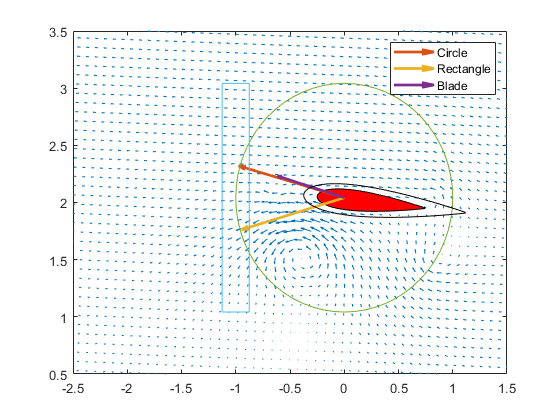

quiver(Xrot3,Yrot3,u3,v3)
xlim([-2.5 1.5])
ylim([0.5 3.5])
hold on
fill(foiltest(:,1),foiltest(:,2),'r')
for i = 1:length(Umean)
quiver(0,2.042,Umean(i),Vmean(i),'LineWidth',2)
end
plot(Ca(:,1),Ca(:,2))
plot(Ra(:,1),Ra(:,2))
plot(foiltest2(:,1),foiltest2(:,2),'k')
hold off
legend('','','Circle','Rectangle','Blade')

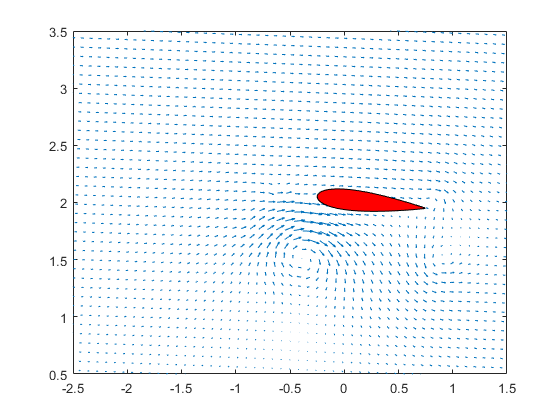

load('Data\U_11P.mat')
load('Data\V_11P.mat')
quiver(Xrot3,Yrot3,U_phase(k).u,V_phase(k).v)
xlim([-2.5 1.5])
ylim([0.5 3.5])
hold on
fill(foiltest(:,1),foiltest(:,2),'r')
hold off

quiver(Xrot3,Yrot3,U,V)
xlim([-2.5 1.5])
ylim([0.5 3.5])
hold on
fill(foiltest(:,1),foiltest(:,2),'r')
hold off

sum(sum((U_phase(k).u-U)))

ans = 0

max(max((U_phase(k).u-U)))

ans = 0

%rt = 0.172/2
rt = 2.042

rt = 2.0420

Uinf = 0.91

Uinf = 0.9100

lam = 1.1

lam = 1.1000

Omega = lam*Uinf/rt

Omega = 0.4902

bv = Omega*rt.*[-cosd(alpha);-sind(alpha)]

bv =     1.0004
    0.0345


u3-bv(1)

ans =    -1.9955   -1.9941   -1.9927   -1.9913   -1.9897   -1.9881   -1.9865   -1.9848   -1.9832   -1.9815   -1.9798   -1.9780   -1.9761   -1.9743   -1.9725   -1.9705   -1.9686   -1.9669   -1.9651   -1.9634   -1.9617   -1.9601   -1.9583   -1.9564   -1.9547   -1.9530   -1.9511   -1.9496   -1.9482   -1.9468   -1.9453   -1.9438   -1.9423   -1.9411   -1.9397   -1.9386   -1.9374   -1.9358   -1.9348   -1.9340   -1.9332   -1.9325   -1.9314   -1.9305   -1.9299   -1.9291   -1.9283   -1.9281   -1.9277   -1.9267
   -1.9960   -1.9946   -1.9932   -1.9916   -1.9900   -1.9884   -1.9867   -1.9850   -1.9833   -1.9816   -1.9798   -1.9779   -1.9760   -1.9742   -1.9722   -1.9702   -1.9683   -1.9664   -1.9646   -1.9628   -1.9611   -1.9593   -1.9574   -1.9555   -1.9537   -1.9520   -1.9501   -1.9485   -1.9471   -1.9456   -1.9440   -1.9424   -1.9409   -1.9397   -1.9383   -1.9372   -1.9358   -1.9342   -1.9333   -1.9325   -1.9313   -1.9306   -1.9297   -1.9288   -1.9280   -1.9271   -1.9262   -1.9260   -1.9256   

U_phase(k).u

ans =     0.9983    0.9969    0.9956    0.9941    0.9926    0.9911    0.9894    0.9877    0.9861    0.9845    0.9828    0.9809    0.9791    0.9773    0.9754    0.9734    0.9716    0.9698    0.9680    0.9663    0.9646    0.9629    0.9611    0.9592    0.9575    0.9557    0.9538    0.9522    0.9508    0.9493    0.9478    0.9463    0.9447    0.9435    0.9421    0.9409    0.9396    0.9379    0.9370    0.9360    0.9352    0.9344    0.9333    0.9324    0.9317    0.9309    0.9299    0.9297    0.9293    0.9282
    0.9989    0.9975    0.9961    0.9946    0.9930    0.9914    0.9896    0.9880    0.9863    0.9846    0.9828    0.9809    0.9790    0.9772    0.9752    0.9732    0.9713    0.9694    0.9675    0.9657    0.9640    0.9622    0.9603    0.9584    0.9565    0.9547    0.9528    0.9512    0.9498    0.9482    0.9466    0.9449    0.9434    0.9421    0.9406    0.9395    0.9381    0.9364    0.9355    0.9346    0.9334    0.9326    0.9316    0.9307    0.9298    0.9289    0.9279    0.9276    0.9271   

U

U =     0.9983    0.9969    0.9956    0.9941    0.9926    0.9911    0.9894    0.9877    0.9861    0.9845    0.9828    0.9809    0.9791    0.9773    0.9754    0.9734    0.9716    0.9698    0.9680    0.9663    0.9646    0.9629    0.9611    0.9592    0.9575    0.9557    0.9538    0.9522    0.9508    0.9493    0.9478    0.9463    0.9447    0.9435    0.9421    0.9409    0.9396    0.9379    0.9370    0.9360    0.9352    0.9344    0.9333    0.9324    0.9317    0.9309    0.9299    0.9297    0.9293    0.9282
    0.9989    0.9975    0.9961    0.9946    0.9930    0.9914    0.9896    0.9880    0.9863    0.9846    0.9828    0.9809    0.9790    0.9772    0.9752    0.9732    0.9713    0.9694    0.9675    0.9657    0.9640    0.9622    0.9603    0.9584    0.9565    0.9547    0.9528    0.9512    0.9498    0.9482    0.9466    0.9449    0.9434    0.9421    0.9406    0.9395    0.9381    0.9364    0.9355    0.9346    0.9334    0.9326    0.9316    0.9307    0.9298    0.9289    0.9279    0.9276    0.9271    0

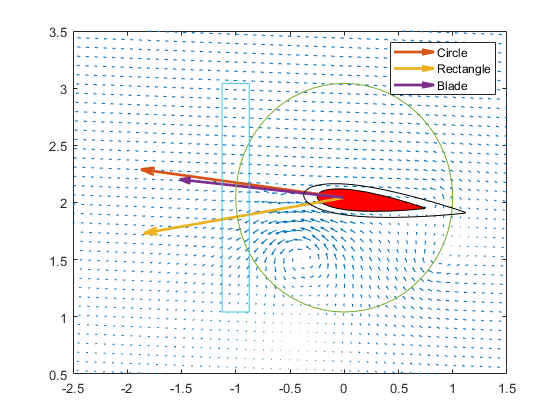

quiver(Xrot3,Yrot3,u3,v3)
xlim([-2.5 1.5])
ylim([0.5 3.5])
hold on
fill(foiltest(:,1),foiltest(:,2),'r')
for i = 1:length(Umean)
quiver(0,2.042,Umean(i)-bv(1),Vmean(i)-bv(2),'LineWidth',2)
end
plot(Ca(:,1),Ca(:,2))
plot(Ra(:,1),Ra(:,2))
plot(foiltest2(:,1),foiltest2(:,2),'k')
hold off
legend('','','Circle','Rectangle','Blade')

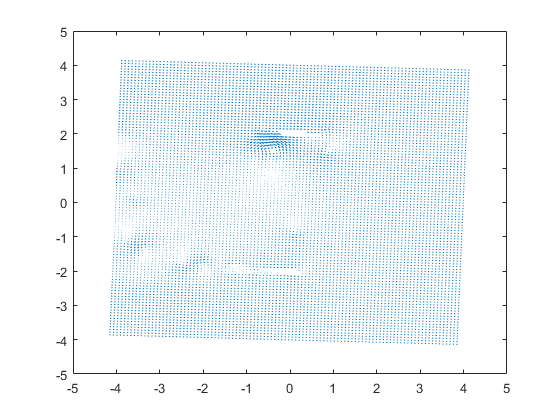

quiver(Xrot3,Yrot3,u3,v3)

Yrot4 = Yrot3-2.042;

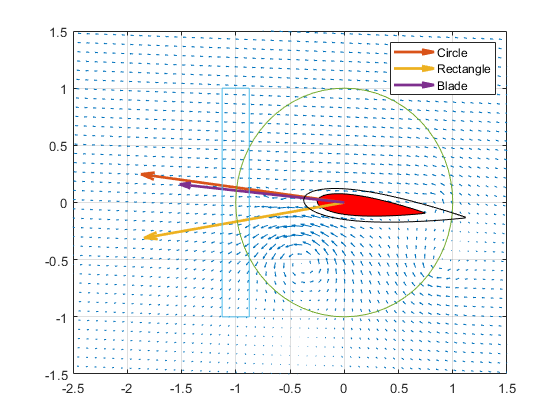

quiver(Xrot3,Yrot4,u3,v3)
xlim([-2.5 1.5])
ylim([-1.5 1.5])
hold on
fill(foiltest(:,1),foiltest(:,2)-2.042,'r')
for i = 1:length(Umean)
quiver(0,0,Umean(i)-bv(1),Vmean(i)-bv(2),'LineWidth',2)
end
plot(Ca(:,1),Ca(:,2)-2.042)
plot(Ra(:,1),Ra(:,2)-2.042)
plot(foiltest2(:,1),foiltest2(:,2)-2.042,'k')
hold off
legend('','','Circle','Rectangle','Blade')
grid on

u4 = zeros(length(u3))

u4 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

v4 = u4

v4 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

for i = 1:length(Xrot3)
    for j = 1:length(Xrot3)
        x = Xrot3(i,j);
        y = Yrot3(i,j);
        rRef = hypot(x,y);
        Omega = lam*Uinf/rt;
        pv = Omega*rRef.*[-cosd(alpha);-sind(alpha)];
        u4(i,j) = u3(i,j)+pv(1);
        v4(i,j) = v3(i,j)+pv(2);
    end
end

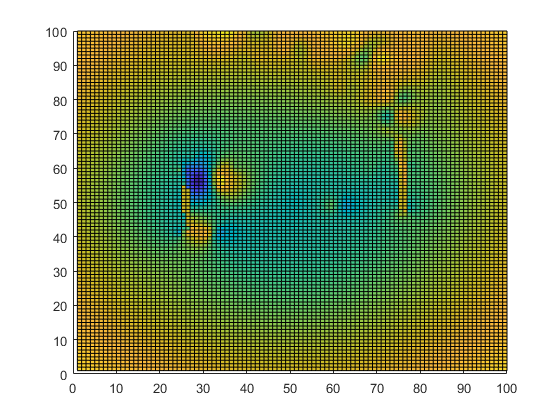

surf(u4)
view([0 90])

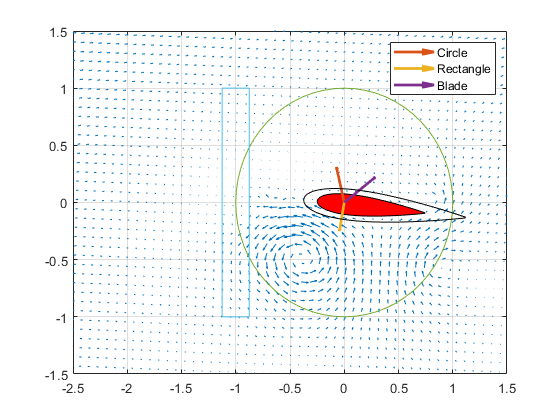

quiver(Xrot3,Yrot4,u4,v4)
xlim([-2.5 1.5])
ylim([-1.5 1.5])
hold on
fill(foiltest(:,1),foiltest(:,2)-2.042,'r')
for i = 1:length(Umean)
quiver(0,0,Umean(i)+bv(1),Vmean(i)+bv(2),'LineWidth',2)
end
plot(Ca(:,1),Ca(:,2)-2.042)
plot(Ra(:,1),Ra(:,2)-2.042)
plot(foiltest2(:,1),foiltest2(:,2)-2.042,'k')
hold off
legend('','','Circle','Rectangle','Blade')
grid on

% quiver(Xrot3,Yrot3,u3,v3)
% xlim([-1 1])
% ylim([1 3])
% hold on
% fill(foiltest(:,1),foiltest(:,2),'r')
% for i = 1%:length(Umean)
% quiver(0,2.042,Umean(i),Vmean(i),'m','LineWidth',2)
% end
% hold off
% legend('','','Circle')%,'Rectangle')

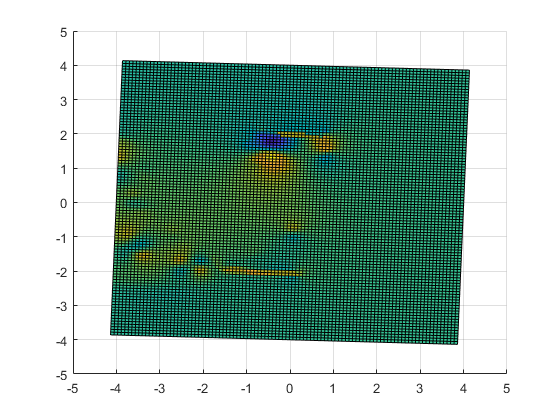

surf(Xrot3,Yrot3,u3)
view([ 0 90])

l = hypot(foiltest(:,1),foiltest(:,2))

l =     2.0892
    2.0892
    2.0892
    2.0891
    2.0890
    2.0889
    2.0888
    2.0886
    2.0884
    2.0882


[M,I] = max(l)

M = 2.1201

I = 75

foiltest(75,:)

ans =    -0.0833    2.1185


[m2,i2] = max(foiltest(:,1))

m2 = 0.7461

i2 = 1

[m3,i3] = min(foiltest(:,1))

m3 = -0.2488

i3 = 102

hypot(m2-m3,foiltest(i2,2)-foiltest(i3,2))

ans = 0.9998